close all
clear all
clc


# 2. Reduced Order Model ( ROM )

## **2.1 Questions**

### 2.2.1


$$X\left(\zeta ,t\right)=\left\lbrack \begin{array}{c}
h\left(0,t\right)\\
h\left(\frac{L}{2},t\right)\\
h\left(L,t\right)\\
v\left(0,t\right)\\
v\left(\frac{L}{2},t\right)\\
v\left(L,t\right)
\end{array}\right\rbrack$$



$$Y\left(\zeta ,t\right)=\left\lbrack \begin{array}{cc}
h\left(0,t\right) & h\left(L,t\right)
\end{array}\right\rbrack$$



$$U\left(\zeta ,t\right)=\left\lbrack \begin{array}{c}
U_1 \left(0,t\right)\\
U_2 \left(L,t\right)
\end{array}\right\rbrack$$


B_b_Model
Frequency_perturbation = pi/2;
Amplitude_perturbation = 1;
Constant_flow          = 1;

dt = 0.01;
%Simulation = sim("Sim_Open_Loop");

%Animation


#### Simulation du système simulé ( Y1 = h (0,t) et Y2 = h(L,t) )

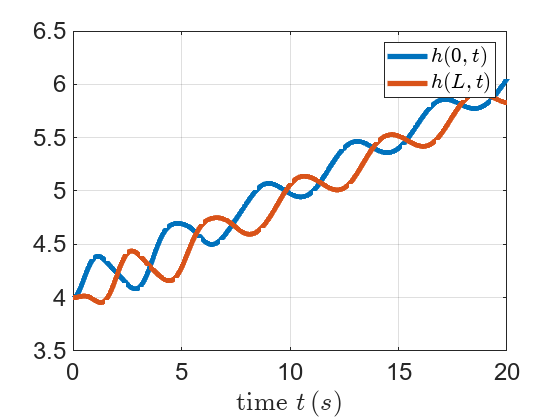

A_b_TrueSystem

%Simulation = sim("Sim_Open_Loop");

%Animation

B_b_Model

#### Simulation du vrai système ( Y1 = h (0,t) et Y2 = h(L,t) )

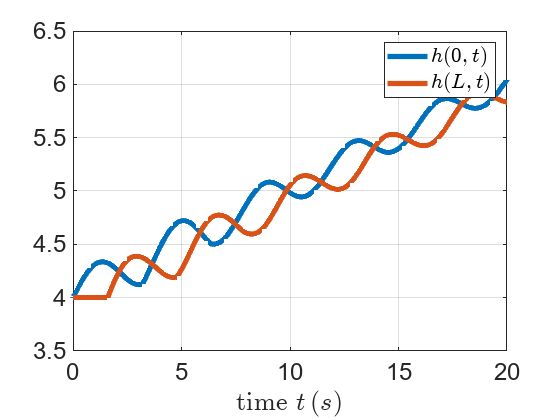

### 2.2.2 

    On a, à l'équilibre, la hauteur de l'eau qui vaut 4m et la vitesse de la montée de l'eau qui vaut 0m/s. Ainsi on a :

                 $Y_{\textrm{eq}} =$ $\left\lbrack \begin{array}{c}
4\\
4
\end{array}\right\rbrack$ et $X_{\textrm{eq}} =$ $\left\lbrack \begin{array}{c}
4\\
4\\
4\\
0\\
0\\
0
\end{array}\right\rbrack$

Ensuite, nous avons $:\;f\left(\zeta ,t\right)=b\ldotp h\left(\zeta ,t\right)\ldotp v\left(\zeta ,t\right)$

Or à l'équilibre $v=0$ donc $f=0$, c'est logique qu'à l'équilibre le débit en entrée et en sortie soit nul.

Donc $U_{\textrm{eq}} =$ $\left\lbrack \begin{array}{c}
0\\
0
\end{array}\right\rbrack$.

Yeq =[4,4].';   % Transposée = A.'
Xeq = [4,4,4,0,0,0].';
Ueq = [0, 0].';

A=jacobian(f,X);
B=jacobian(f,U);
C=jacobian(h,X);
D=jacobian(h,U);

A=eval(subs(A, [X; U], [Xeq; Ueq]));
B=eval(subs(B, [X; U], [Xeq; Ueq]));
C=eval(subs(C, [X; U], [Xeq; Ueq]));
D=eval(subs(D, [X; U], [Xeq; Ueq]));


### 2.2.3


sys_lin = ss(A, B, C, D);

t = (0:dt:20)'; % Vecteur temps de 20s

% Entrée U(t)

U1 = Constant_flow + Amplitude_perturbation * sin(Frequency_perturbation * t);
U2 = zeros(size(t));
U = [U1, U2]; 

% Linéarisation de U
u = U - ones(length(t), 1) * [Ueq(1), Ueq(2)];

% Simuler la réponse linéaire y(t)
[y, t_lin] = lsim(sys_lin, u, t);

% On reprends la sortie réelle Y
 Y = y + ones(length(t), 1) * [Yeq(1), Yeq(2)];
 
% figure;
% set(gcf, 'Position', [100, 100, 800, 600]);
% 
% plot(t_lin, Y(:, 1), 'b', 'LineWidth',2);
% title('Y_1(t) = h(0,t) et Y2 = h(L,t)');
% xlabel('Temps (s)');
% ylabel('Hauteur (m)');
% grid on;
% hold on;
% 
% plot(t_lin, Y(:, 2), 'r','LineWidth',2);
% xlabel('Temps (s)');
% ylabel('Hauteur (m)');
% legend('Y1 = h(0,t)','Y2 = h(L,t)');
% grid on;

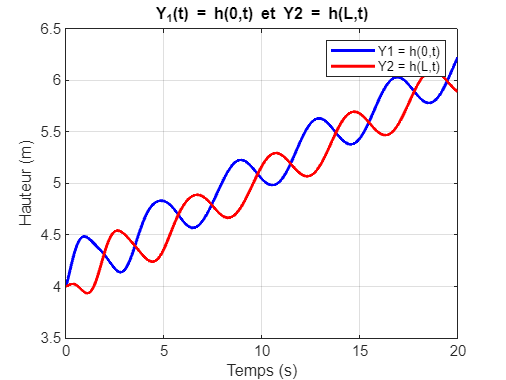

### 2.2.4

    On cherche les valeurs propres avec la fonction eig.

ValP=eig(A);


On trouve :

    
$$\lambda_1 =0\ldotp 4000+3\ldotp 7352i$$
 

    
$$\lambda_2 =-0\ldotp 4000-3\ldotp 7352i$$
 

    
$$\lambda_3 =-0\ldotp 0000+0\ldotp 0000i$$
 

    
$$\lambda_4 =-0\ldotp 4000+2\ldotp 1317i$$
 

    
$$\lambda_5 =-0\ldotp 4000-2\ldotp 1317i$$
 

    
$$\lambda_6 =-0\ldotp 8000+0\ldotp 0000i$$
 

### 2.2.5

    On a bien les valeurs propres à partie réelle négative inférieures ou égales à 0 et celle à 0 est simple donc le système est stable au sens de Lyapunov.

### 2.2.6

    Etant donné qu'on a une valeur propre à 0, le système n'est pas asymptotiquement stable ( car partie réelle n'est pas strictement négative ).

# 3. Analysis of the linearized model

## 3.1 Questions

### 3.1.1 

Qc = ctrb(A,B);
rang = rank(Qc); % 5
[M,Diag] = eig(A);
B_diag = inv(M)*B;

Le système n'est pas commandable car $\textrm{rang}\left(\textrm{Qc}\right)\not= 6$.

On a $B_{\textrm{diag}} =M^{-1} B$

Donc $B_{\textrm{diag}} =\left\lbrack \begin{array}{cc}
0+0\ldotp 424i & 0-0\ldotp 424i\\
0-0\ldotp 424i & 0+0\ldotp 424i\\
0\ldotp 1732 & -0\ldotp 1732\\
0\ldotp 3164-0\ldotp 0594i & 0\ldotp 3164-0\ldotp 0594i\\
0\ldotp 3164+0\ldotp 0594i & 0\ldotp 3164+0\ldotp 0594i\\
0 & 0
\end{array}\right\rbrack$

Le mode qui n'est pas commandable est la valeur propre -0.8 ( la dernière ligne est nulle ).

### 3.3.2

Qo = obsv(A,C);
rang = rank(Qo);
C_diag = C*M;

Le système n'est pas observable car rang(Qo) != 6.

On a $C_{\textrm{diag}} =\textrm{CM}$

Donc $C_{\textrm{diag}} =\left\lbrack \begin{array}{cccccc}
-0\ldotp 0379-0\ldotp 3538i & -0\ldotp 0379+0\ldotp 3538i & 0\ldotp 5774 & 0\ldotp 474 & 0\ldotp 474 & 0\\
-0\ldotp 0379-0\ldotp 3538i & -0\ldotp 0379+0\ldotp 3538i & 0\ldotp 5774 & -0\ldotp 474 & -0\ldotp 474 & 0
\end{array}\right\rbrack$ 

Le mode qui n'est pas observable est la valeur propre -0.8 ( car c'est la dernière colonne qui est nulle.

### 3.3.3

    Le mode non commandable n'est pas asymptotiquement stable donc le système n'est pas stabilisable.

### 3.3.4

    Le mode non observable n'est pas asymptotiquement stable donc le système n'est pas détectable.

# 4 State feedback control

## 4.2 Questions

### 4.2.1

V = [-1 1 0 0 0 0; 
    0 0 1+1i 1-1i 0 0;
    -1 -1 0 0 0 0;
    0 0 -1 -1 1 1;
    0 0 0 0 1 -1;
    0 0 1 1 1 1];

invV = inv(V);

Adiag = [-15 0 0 0 0 0; 
    0 -10 0 0 0 0;
    0 0 -0.5+1.8i 0 0 0;
    0 0 0 -0.5-1.8i 0 0;
    0 0 0 0 -1 0;
    0 0 0 0 0 -0.8];

C_sortie_voulue = C*V

C_sortie_voulue =     -1     1     0     0     0     0
    -1    -1     0     0     0     0


On executant C*V, on se retrouve avec une matrice montrant bien que la sortie est largement dominée par les poles $\lambda_1 \;\textrm{et}\;\lambda_2$.

### 4.2.2

    On va trouver K en faisant le changement de variable $x=V\sigma \;\textrm{et}\;u=-\textrm{Kx}\;\textrm{on}\;a\;:$

                                                 $\dot{\sigma}$ = $V^{-1} \left(A-B\;K\right)V\sigma \;$

Avec $V=\left\lbrack \begin{array}{cccccc}
\textrm{v1} & \textrm{v2} & \textrm{v3} & \textrm{v4} & \textrm{v5} & \textrm{v6}
\end{array}\right\rbrack$

Donc $V=\left\lbrack \begin{array}{cccccc}
-1 & 1 & 0 & 0 & 0 & 0\\
0 & 0 & 1+i & 1-i & 0 & 0\\
-1 & -1 & 0 & 0 & 0 & 0\\
0 & 0 & -1 & -1 & 1 & 1\\
0 & 0 & 0 & 0 & 1 & -1\\
0 & 0 & 1 & 1 & 1 & 1
\end{array}\right\rbrack$

ValPV=[-15;-10;-0.5+1.8i;-0.5-1.8i;-1;-0.8];

Q1=[ValPV(1)*eye(6)-A B];
Q2=[ValPV(2)*eye(6)-A B];
Q3=[ValPV(3)*eye(6)-A B];
Q4=[ValPV(4)*eye(6)-A B];
Q5=[ValPV(5)*eye(6)-A B];
Q6=[ValPV(6)*eye(6)-A B];

R1=null(Q1);
R2=null(Q2);
R3=null(Q3);
R4=null(Q4);
R5=null(Q5);
R6=null(Q6);

N1=R1(1:6,:);
N2=R2(1:6,:);
N3=R3(1:6,:);
N4=R4(1:6,:);
N5=R5(1:6,:);
N6=R6(1:6,:);

z1=inv(N1'*N1)*N1'*V(:,1);
z2=inv(N2'*N2)*N2'*V(:,2);
z3=inv(N3'*N3)*N3'*V(:,3);
z4=inv(N4'*N4)*N4'*V(:,4);
z5=inv(N5'*N5)*N5'*V(:,5);
z6=inv(N6'*N6)*N6'*V(:,6);

Vapp1=N1*z1;
Vapp2=N2*z2;
Vapp3=N3*z3;
Vapp4=N4*z4;
Vapp5=N5*z5;
Vapp6=N6*z6;

Wapp1= R1(7:8,:)*z1;
Wapp2= R2(7:8,:)*z2;
Wapp3= R3(7:8,:)*z3;
Wapp4= R4(7:8,:)*z4;
Wapp5= R5(7:8,:)*z5;
Wapp6= R6(7:8,:)*z6;

W = [Wapp1 Wapp2 Wapp3 Wapp4 Wapp5 Wapp6];


Voici les vecteurs propres obtenus :

Vapp = [Vapp1 Vapp2 Vapp3 Vapp4 Vapp5 Vapp6]

Vapp =   -0.8289 + 0.0000i   0.9363 + 0.0000i   0.0544 - 0.0040i   0.0544 + 0.0040i  -0.1013 + 0.0000i  -0.0000 + 0.0000i
   0.3942 + 0.0000i   0.0000 + 0.0000i   0.2907 + 0.6797i   0.2907 - 0.6797i  -0.0000 + 0.0000i   0.0000 + 0.0000i
  -0.8289 + 0.0000i  -0.9363 + 0.0000i   0.0544 - 0.0040i   0.0544 + 0.0040i   0.1013 + 0.0000i  -0.0000 + 0.0000i
   0.2532 + 0.0000i  -0.1995 + 0.0000i  -1.1490 + 0.1945i  -1.1490 - 0.1945i   0.9931 + 0.0000i   1.0000 + 0.0000i
  -0.0000 + 0.0000i  -0.1995 + 0.0000i   0.0000 - 0.0000i   0.0000 + 0.0000i   0.9931 + 0.0000i  -1.0000 + 0.0000i
  -0.2532 + 0.0000i  -0.1995 + 0.0000i   1.1490 - 0.1945i   1.1490 + 0.1945i   0.9931 + 0.0000i   1.0000 + 0.0000i


Kapp = W*Vapp^-1;

Et enfin, le gain K trouvé en fonction deces vecteurs propres. On fait partie real car un gain ne peut être complexe.

K_app_real = real(Kapp)

K_app_real =    17.9247   -0.3013    0.9247   -1.7117   -1.2177    0.4940
   -0.9247    0.3013  -17.9247    0.4940   -1.2177   -1.7117


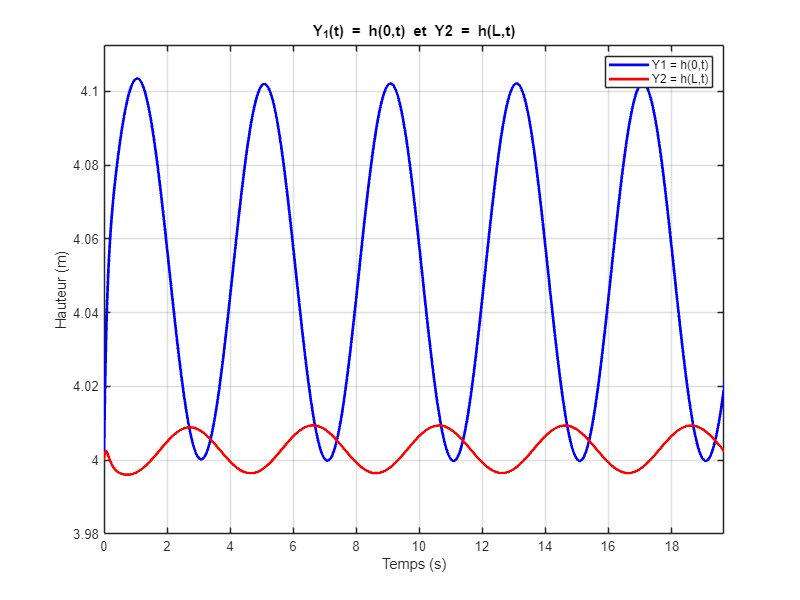


K=place(A,B,ValPV);

sys = ss(A-B*K_app_real, B, C, D);

t = (0:dt:20)'; % Vecteur temps de 20s

% Entrée U(t)

U1 = Constant_flow + Amplitude_perturbation * sin(Frequency_perturbation * t);
U2 = zeros(size(t));
U = [U1, U2]; 

% Linéarisation de U
u = U - ones(length(t), 1) * [Ueq(1), Ueq(2)];

% Simuler la réponse linéaire y(t)
[y, t_lin] = lsim(sys, u, t);

% On reprends la sortie réelle Y
 Y = y + ones(length(t), 1) * [Yeq(1), Yeq(2)];

figure;
set(gcf, 'Position', [100, 100, 800, 600]);

plot(t_lin, Y(:, 1), 'b', 'LineWidth',2);
title('Y_1(t) = h(0,t) et Y2 = h(L,t)');
xlabel('Temps (s)');
ylabel('Hauteur (m)');
grid on;
hold on;

plot(t_lin, Y(:, 2), 'r','LineWidth',2);
xlabel('Temps (s)');
ylabel('Hauteur (m)');
legend('Y1 = h(0,t)','Y2 = h(L,t)');
grid on;

 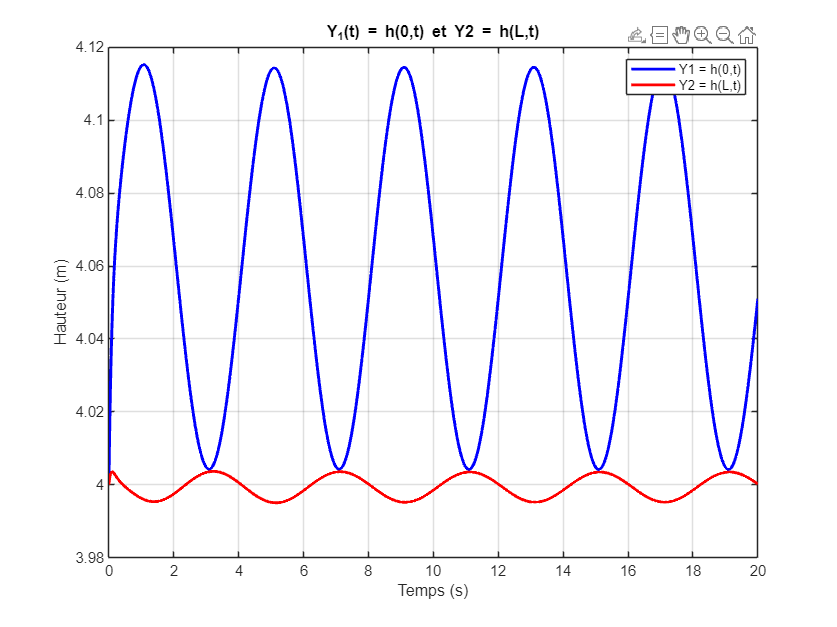

On voit bien que le système n'est pas corrigé avec précision, mais oscille avec la valeur désirée. Ce qui veut dire que $\lambda_1$ et $\lambda_2$ ne sont pas dominants car sinon il n'y aurait pas d'oscillation. On va donc chercher à corriger ce comportement.

### **4.2.3**

C_sortie_obtenue = C*Vapp

C_sortie_obtenue =   -0.8289 + 0.0000i   0.9363 + 0.0000i   0.0544 - 0.0040i   0.0544 + 0.0040i  -0.1013 + 0.0000i  -0.0000 + 0.0000i
  -0.8289 + 0.0000i  -0.9363 + 0.0000i   0.0544 - 0.0040i   0.0544 + 0.0040i   0.1013 + 0.0000i  -0.0000 + 0.0000i


La nouvelle matrice est globalement toujours dominée par les 2 premiers pôles mais aussi légèrement par les autres. C'est dû au fait que nous avons réussi à approcher les vecteurs voulus mais nous n'avons pas obtenu exactement leurs valeurs.

### 4.4.1


$$J\left\lbrack u\left(t\right)\right\rbrack =\int_0^{\infty } \left\lbrack \gamma {y\left(t\right)}^T y\left(t\right)+{u\left(t\right)}^T u\left(t\right)\right\rbrack \textrm{dt}$$



$$\textrm{Donc}\;:\;J\left\lbrack u\left(t\right)\right\rbrack =\int_0^{\infty } \left\lbrack {x\left(t\right)}^T \gamma C^T \textrm{Cx}\left(t\right)+{u\left(t\right)}^T u\left(t\right)\right\rbrack \textrm{dt}$$


On obtient donc $Q=$$\gamma C^T C$ et $R=I_2$ .

R=eye(2);

gamma=1000;
Q=gamma*(C.')*C;

On a donc : $R=\left\lbrack \begin{array}{cc}
1 & 0\\
0 & 1
\end{array}\right\rbrack$ e t $Q=\;$$\left\lbrack \begin{array}{cccccc}
1000 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 1000 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0
\end{array}\right\rbrack$

### 4.4.2

  On utilise la fonction lqr() pour déterminer K, comme dit dans le cours.

[K2,P,BF_p]=lqr(A,B,Q,R);

On a P tel que $P\ldotp A+A^T \;\ldotp P+Q-{P\ldotp B\ldotp R}^{-1} {\ldotp B}^T \ldotp P=0$

On obtient $K=$$\left\lbrack \begin{array}{cccccc}
31\ldotp 3260 & 0\ldotp 2554 & 0\ldotp 0414 & -1\ldotp 9065 & -1\ldotp 6282 & 0\ldotp 2783\\
-0\ldotp 0414 & -0\ldotp 2554 & -31\ldotp 3260 & 0\ldotp 2783 & -1\ldotp 6282 & -1\ldotp 9065
\end{array}\right\rbrack$

# 5. Observer-based state feedback controller

### 5.1.1

Calcul du gain L à l'aide de la méthode LQR pour le retour d'observateur d'état :

Q=4000*eye(6);
[K_d,P_d,BF_p_d]=lqr(A',C',Q,R);
L = K_d';

On trouve donc notre gain L en utilisant le methode linear-quadratic regulator : $L=\left\lbrack \begin{array}{cc}
65\ldotp 4760 & 0\ldotp 9070\\
21\ldotp 5807 & 21\ldotp 5807\\
0\ldotp 9070 & 65\ldotp 4760\\
-53\ldotp 7950 & -30\ldotp 9354\\
-23\ldotp 8093 & 23\ldotp 8093\\
30\ldotp 9354 & 53\ldotp 7950
\end{array}\right\rbrack$.

### 5.1.2

En simulant le système avec le retour par observateur d'état avec les gains calculés, celui-ci est particulièrement stable (pour le modèle linéaire) grâce à la méthode du LQR. En faisant utilisant le gain calculé avec la méthode générale, on obtient un système presque aussi stable mais pas autant qu'avec la méthode du LQR.

Ci-dessous une simulation du canal en boucle fermé avec le gain LQR :

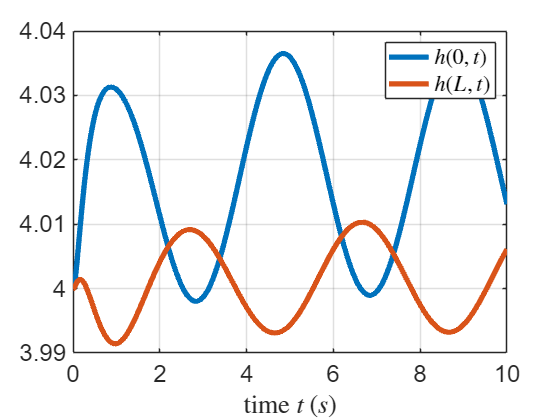

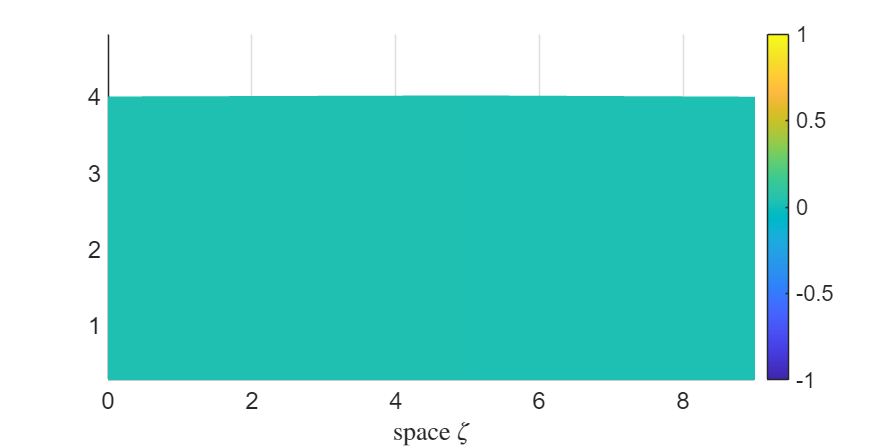

A_construit = A;
B_construit = B;
C_construit = C;
Simulation = sim("Closed_Loop_LQR");
Animation()

## Conclusion du pojet

Au cours de ce BE, nous avons pu stabiliser le canal grâce à plusieurs méthodes : celle générale et celle du LQR. D'après les simulations, celle du LQR est plus otpimales, elle permet une meilleur stabilité du système. Nous ne pouvons cependant pas conclure sur la simulation réelle (nous n'avons pas réussi) mais celle-ci aurait pu apporter une meilleur conclusion à propos des différentes méthodes mais sur le cas non-linéaire et voir laquelle est plus efficace.

## Ouverture sur un autre système

Un sous-marin qu'il faut controller à rester sur un certain niveau sous l'eau. Toutes les constantes sont à de definir selon le sous-marin.


$$\begin{array}{l}
\sum F_x =F_P -R_x =m\ddot{x} =T-k\dot{x} \\
\sum F_z =\left(m+m_T \right)g-R_z -F_B =m\;\ddot{z} =\left(m+m_T \right)g-k\dot{z} -\rho \;\textrm{gV}\\
x=\left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
x_4 \\
x_5 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
x\\
z\\
v_x \\
v_z \\
m_T 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\textrm{Position}\;\textrm{le}\;\textrm{long}\;x\\
\textrm{Position}\;\textrm{le}\;\textrm{long}\;\textrm{du}\;z\\
\textrm{Vitesse}\;\textrm{le}\;\textrm{long}\;\textrm{du}\;x\\
\textrm{Vitesse}\;\textrm{le}\;\textrm{long}\;\textrm{du}\;z\\
\textrm{Masse}\;\textrm{du}\;\textrm{reservoir}
\end{array}\right\rbrack \\
u=\left\lbrack \begin{array}{c}
u_1 \\
u_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
T\\
q_c 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\textrm{La}\;\textrm{pousser}\;\textrm{des}\;\textrm{hélices}\\
\textrm{Flux}\;\textrm{du}\;\textrm{compresseur}
\end{array}\right\rbrack \\
y=\left\lbrack \begin{array}{c}
y_1 \\
y_2 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
z\\
v_x 
\end{array}\right\rbrack 
\end{array}$$



$$\[
\begin{cases}
\dot{x}_1 =x_3 \\
\dot{x}_2 =x_4 \\
\dot{x}_3 = \frac{-k}{m}x_3 + \frac{1}{m}u_1\\
\dot{x}_4 =  \frac{-k}{m} x_4 +\frac{g}{m}*x_5 + g*[1-\frac{\rho*V}{m}] \\
\dot{x}_5 = u_2 \\
\end{cases}
\]$$



$$\;\dot{x} =\left\lbrack \begin{array}{ccccc}
0 & 0 & 1 & 0 & 0\\
0 & 0 & 0 & 1 & 0\\
0 & 0 & -\frac{k}{m}0 & 0 & 0\\
0 & 0 & 0 & -\frac{k}{m} & \frac{g}{m}\\
0 & 0 & 0 & 0 & 0
\end{array}\right\rbrack *\left\lbrack \begin{array}{c}
x\\
z\\
v_x \\
v_z \\
m_T 
\end{array}\right\rbrack +\left\lbrack \begin{array}{cc}
0 & 0\\
0 & 0\\
\frac{1}{m} & 0\\
0 & 0\\
0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
u_1 \\
u_2 
\end{array}\right\rbrack$$


Schéma du sous-marin représenté avec sa dynamique :